# Laboratorio No. 4

Punto 1-5 pura carreta :V

addpath 'C:\Program Files\MATLAB\R2020b\toolbox\rvctools'

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com


clc; 
clear all;
close all;

## 6 Iniciando

### 6.1 Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.


L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.09365; L7=  0.09465; L8= 0.0823; 
L9 = 0.05; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',pi,'a',L3,'d', L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',-pi,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|     0.1197|      0.425|      3.142|          0|
|  4|         q4|    0.09365|     0.3922|     -3.142|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

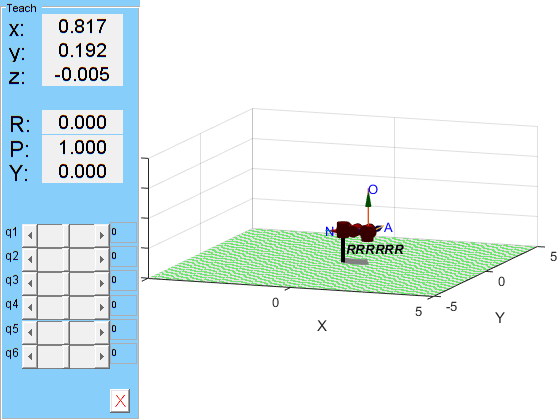

UR5_RVC.plot([0 0 0 0 0 0],'workspace',[-5 5 -5 5 -1 3],'noa','view',[20 10]);
UR5_RVC.teach;

### 6.2 Considerando el robot asignado, construya el modelo del robot utilizando RST.

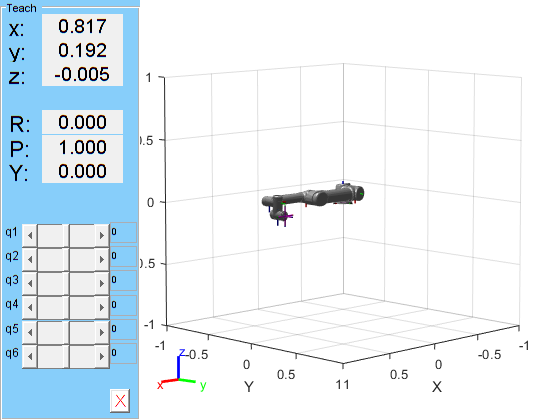

UR5_RST = loadrobot("universalUR5");
show(UR5_RST);

### 6.3 Compare los dos métodos.

### 6.4 Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

## 7 Modelo geométrico directo

### 7.1 Halle el modelo geométrico directo de su robot asignado usando MTH. 

clc; 
clear all;
close all;
syms  q1 q2 q3 q4 q5 q6 L1 L2 L3 L4 L5 L6 L7 L8 L9

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',sym(pi),'a',L3,'d', L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',sym(-pi),'a',L5,'d',L6,'offset',sym(-pi),'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',sym(pi/2),'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]

UR5_RVC = struct with fields:
    tool: [4×4 sym]



%Calculo de T_0_1
T_0_1 = L(1).A(q1) 

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_1_2
T_1_2 = L(2).A(q2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & L_{2}\\ -\sin\left(q_{2}\right) & -\cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_2_3
T_2_3 = L(3).A(q3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & L_{3}\\ -\sin\left(q_{3}\right) & -\cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & -1 & -L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_3_4
T_3_4 = L(4).A(q4)

$$T\_3\_4 = \left(\begin{array}{cccc} -\cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & L_{5}\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & -1 & -L_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_4_5
T_4_5 = L(5).A(q5)

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ 0 & 0 & -1 & -L_{7}\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_5_6
T_5_6 = L(6).A(q6)

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & L_{8}\\ -\sin\left(q_{6}\right) & -\cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de MTH general

T_0_Tool = T_0_1 * T_0_1 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

$$T\_0\_Tool = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{6}\right)\,\sigma_{1}+\cos\left(q_{5}\right)\,\sin\left(q_{6}\right)\,\sigma_{2} & \cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sigma_{2}-\sin\left(q_{6}\right)\,\sigma_{1} & \sin\left(q_{5}\right)\,\sigma_{2} & L_{5}\,\sigma_{4}-L_{7}\,\sigma_{1}+L_{3}\,\sigma_{5}+L_{8}\,\sin\left(q_{5}\right)\,\sigma_{2}+L_{9}\,\sin\left(q_{5}\right)\,\sigma_{2}\\ \cos\left(q_{5}\right)\,\sin\left(q_{6}\right)\,\sigma_{1}-\cos\left(q_{6}\right)\,\sigma_{2} & \sin\left(q_{6}\right)\,\sigma_{2}+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sigma_{1} & \sin\left(q_{5}\right)\,\sigma_{1} & L_{7}\,\sigma_{2}-L_{5}\,\sigma_{3}+2\,L_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{1}\right)+L_{8}\,\sin\left(q_{5}\right)\,\sigma_{1}+L_{9}\,\sin\left(q_{5}\right)\,\sigma_{1}\\ -\sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 2\,L_{1}-L_{4}+L_{6}+L_{8}\,\cos\left(q_{5}\right)+L_{9}\,\cos\left(q_{5}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{4}\right)\,\sigma_{4}-\cos\left(q_{4}\right)\,\sigma_{3}\\ \sigma_{2}=\sin\left(q_{4}\right)\,\sigma_{3}+\cos\left(q_{4}\right)\,\sigma_{4}\\ \sigma_{3}=\sin\left(q_{3}\right)\,\sigma_{5}-2\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{4}=\cos\left(q_{3}\right)\,\sigma_{5}+2\,\cos\left(q_{1}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}={\cos\left(q_{1}\right)}^{2}-{\sin\left(q_{1}\right)}^{2} \end{array}$$

### 7.2 Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.09365; L7=  0.09465; L8= 0.0823; 
L9 = 0.05; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',pi,'a',L3,'d', L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',-pi,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|     0.1197|      0.425|      3.142|          0|
|  4|         q4|    0.09365|     0.3922|     -3.142|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                                       
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|    0.08916|          0|          0|          0|             
|  2|         q2|     0.1358|          0|     -1.571|          0|             
|  3|         q3|     0.1197|      0.425|      3.142|          0|             
|  4|         q4|    0.09365|     0.3922|     -3.142|     -3.142|             
|  5|         q5|    0.09465|          0|      1.571|          0|             
|  6|         q6|     0.0823|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                     


% Caso 1

T_0_1 = L(1).A(0.5); T_1_2 = L(2).A(0.2); T_2_3 = L(3).A(0.4);
T_3_4 = L(4).A(0.5); T_4_5 = L(5).A(0);   T_5_6 = L(6).A(1.5);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.8546   -0.1994   -0.4794    0.5623
    0.4669   -0.1089    0.8776    0.5831
   -0.2272   -0.9738    0.0000   -0.0078
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.5623
    0.5831
   -0.0078



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =     0.8546   -0.1994   -0.4794
    0.4669   -0.1089    0.8776
   -0.2272   -0.9738    0.0000


roll =atan2(mRotacion(3,2),mRotacion(3,3))*(180/pi)

roll = -90

pitch=atan2(-mRotacion(3,1),sqrt(mRotacion(1,1)^2+mRotacion(2,1)^2))*(180/pi) %revisar

pitch = 13.1324

yaw = atan2(mRotacion(2,1),mRotacion(1,1))*(180/pi)

yaw = 28.6479


cGeneral1 = [vPosicion', roll, pitch, yaw]

cGeneral1 =     0.5623    0.5831   -0.0078  -90.0000   13.1324   28.6479



% Caso 2

T_0_1 = L(1).A(-pi/2); T_1_2 = L(2).A(0.3); T_2_3 = L(3).A(0);
T_3_4 = L(4).A(pi/2); T_4_5 = L(5).A(0.4);   T_5_6 = L(6).A(1.2);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =    -0.3630   -0.1411    0.9211    0.2317
   -0.0925    0.9890    0.1151   -0.6751
   -0.9272   -0.0434   -0.3720   -0.1736
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.2317
   -0.6751
   -0.1736



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =    -0.3630   -0.1411    0.9211
   -0.0925    0.9890    0.1151
   -0.9272   -0.0434   -0.3720


roll =atan2(mRotacion(3,2),mRotacion(3,3))*(180/pi)

roll = -173.3444

pitch=atan2(-mRotacion(3,1),sqrt(mRotacion(1,1)^2+mRotacion(2,1)^2))*(180/pi) %revisar

pitch = 68.0035

yaw = atan2(mRotacion(2,1),mRotacion(1,1))*(180/pi)

yaw = -165.7053


cGeneral2 = [vPosicion', roll, pitch, yaw]

cGeneral2 =     0.2317   -0.6751   -0.1736 -173.3444   68.0035 -165.7053



% Caso 3

T_0_1 = L(1).A(0); T_1_2 = L(2).A(1); T_2_3 = L(3).A(-0.5);
T_3_4 = L(4).A(2); T_4_5 = L(5).A(1);   T_5_6 = L(6).A(0.5);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =    -0.5504   -0.2759   -0.7880    0.1863
   -0.4034   -0.7385    0.5403    0.1813
   -0.7310    0.6153    0.2952   -0.5320
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.1863
    0.1813
   -0.5320



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =    -0.5504   -0.2759   -0.7880
   -0.4034   -0.7385    0.5403
   -0.7310    0.6153    0.2952


roll =atan2(mRotacion(3,2),mRotacion(3,3))*(180/pi)

roll = 64.3715

pitch=atan2(-mRotacion(3,1),sqrt(mRotacion(1,1)^2+mRotacion(2,1)^2))*(180/pi) %revisar

pitch = 46.9663

yaw = atan2(mRotacion(2,1),mRotacion(1,1))*(180/pi)

yaw = -143.7608


cGeneral3 = [vPosicion', roll, pitch, yaw]

cGeneral3 =     0.1863    0.1813   -0.5320   64.3715   46.9663 -143.7608



% Caso 4

T_0_1 = L(1).A(-1); T_1_2 = L(2).A(-0.3); T_2_3 = L(3).A(-pi/5);
T_3_4 = L(4).A(0.4); T_4_5 = L(5).A(0.2);   T_5_6 = L(6).A(1);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.3862   -0.1794    0.9048    0.5980
   -0.9108    0.0808    0.4048   -0.4882
   -0.1457   -0.9805   -0.1322    0.0001
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.5980
   -0.4882
    0.0001



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =     0.3862   -0.1794    0.9048
   -0.9108    0.0808    0.4048
   -0.1457   -0.9805   -0.1322


roll =atan2(mRotacion(3,2),mRotacion(3,3))*(180/pi)

roll = -97.6814

pitch=atan2(-mRotacion(3,1),sqrt(mRotacion(1,1)^2+mRotacion(2,1)^2))*(180/pi) %revisar

pitch = 8.3782

yaw = atan2(mRotacion(2,1),mRotacion(1,1))*(180/pi)

yaw = -67.0242


cGeneral4 = [vPosicion', roll, pitch, yaw]

cGeneral4 =     0.5980   -0.4882    0.0001  -97.6814    8.3782  -67.0242


### 7.3 Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores. 

%% Haciendo uso del Toolbox de Peter Corke

% Caso 1

q = [0.5 0.2 0.4 0.5 0 1.5];
Tc1 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 1

Tc1 =     0.8546   -0.1994   -0.4794    0.5623
    0.4669   -0.1089    0.8776    0.5831
   -0.2272   -0.9738    0.0000   -0.0078
         0         0         0    1.0000




gen1=[transl(Tc1)', tr2rpy(Tc1,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen1 =     0.5623    0.5831   -0.0078  -90.0000  -28.6479   13.1324



% Caso 2

q = [-pi/2 0.3 0 pi/2 0.4 1.2];
Tc2 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 2

Tc2 =    -0.3630   -0.1411    0.9211    0.2317
   -0.0925    0.9890    0.1151   -0.6751
   -0.9272   -0.0434   -0.3720   -0.1736
         0         0         0    1.0000



gen2=[transl(Tc2)', tr2rpy(Tc2,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen2 =     0.2317   -0.6751   -0.1736 -162.8113   67.0817  158.7549



% Caso 3

q = [0 1 -0.5 2 1 0.5];
Tc3 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 3

Tc3 =    -0.5504   -0.2759   -0.7880    0.1863
   -0.4034   -0.7385    0.5403    0.1813
   -0.7310    0.6153    0.2952   -0.5320
         0         0         0    1.0000


gen3=[transl(Tc3)', tr2rpy(Tc3,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen3 =     0.1863    0.1813   -0.5320  -61.3517  -51.9991  153.3810



% Caso 4

q = [-1 -0.3 -pi/5 0.4 0.2 1];
Tc4 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 4

Tc4 =     0.3862   -0.1794    0.9048    0.5980
   -0.9108    0.0808    0.4048   -0.4882
   -0.1457   -0.9805   -0.1322    0.0001
         0         0         0    1.0000


gen4=[transl(Tc4)', tr2rpy(Tc4,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen4 =     0.5980   -0.4882    0.0001 -108.0921   64.7972   24.9205



%% Usando el Toolbox de Matlab

ur5=loadrobot("universalUR5",'Gravity',[0 0 -9.81])

ur5 =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 -9.8100]
    DataFormat: 'struct'


ur5.DataFormat = 'row';
showdetails(ur5)

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e


transform = getTransform(ur5,[0 0 0 0 0 0],'base_link','tool0');
